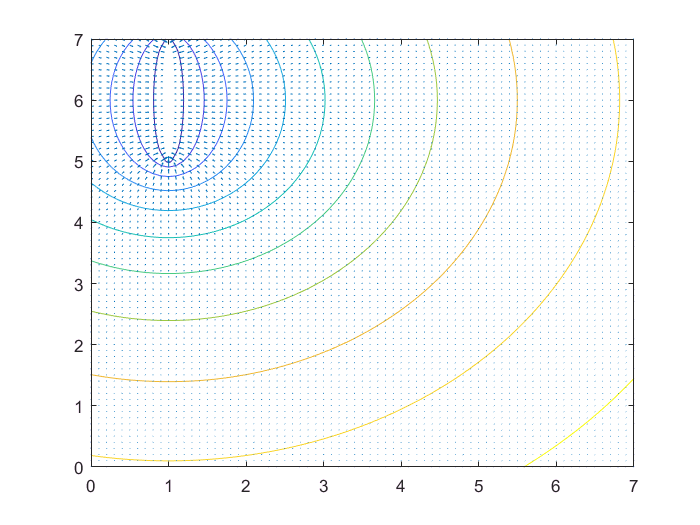

clear all;
%edit your ranges to display here.  important to not include the actual
%location of your object in this grid of points or it will give you
%infinities
[x,y]=meshgrid(0:0.1:7,0:0.1:7);
[xlim,ylim] = size(x);
V = zeros(xlim, ylim);
r =0.11;
u_scale = 10.5;

for i=1:xlim
    
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)   -log(sqrt((x(i,j)-r*cosd(theta)-1).^2 + (y(i,j)-sind(theta)- 6).^2)).*r;
        
       
        V(i,j) = integral(dV,0,360);
        
        
       
    end
end

hold off

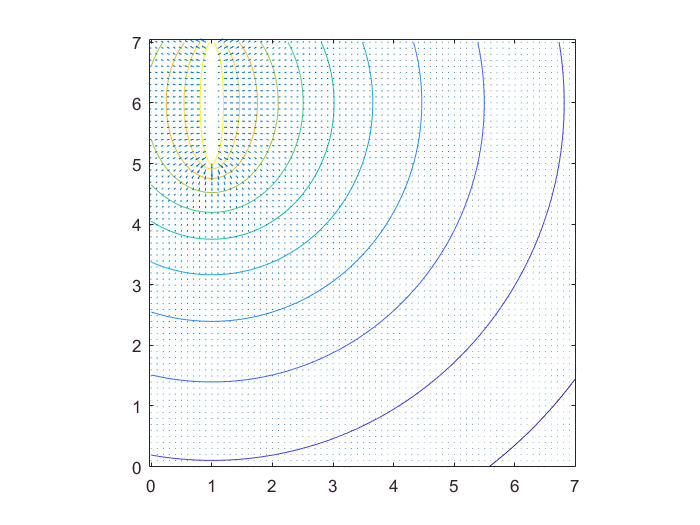

contour(x,y,V)
[Ex,Ey] = gradient(V);
hold on
quiver(x,y,-Ex,-Ey)
hold off
axis 'equal'

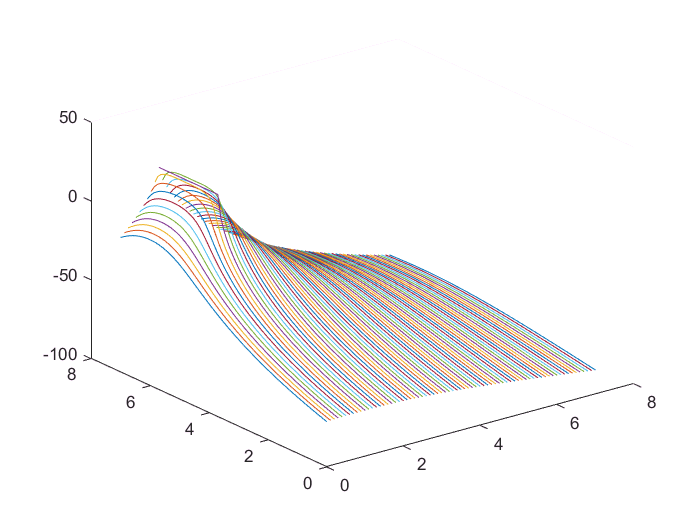


plot3(x,y,V)

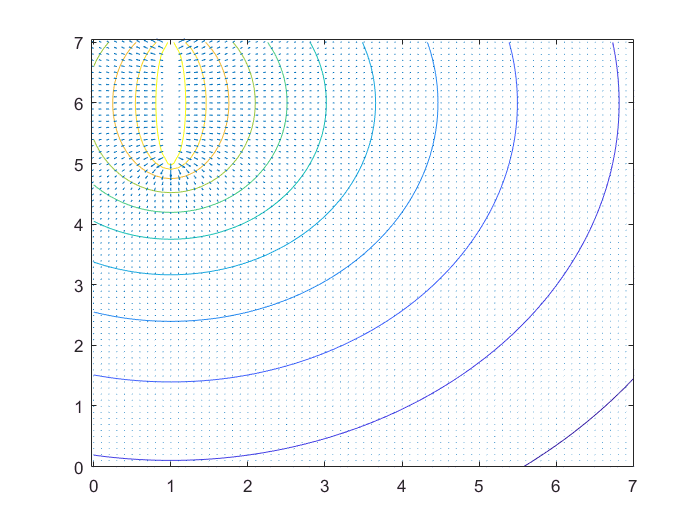

%f(xy)= x(1)*y(1) - (x(1))^2 - (y(1))^2 - 2*x(1) - 2*y(1)+4

%Second thing-box A
%edit your ranges to display here.  important to not include the actual
%location of your object in this grid of points or it will give you
%infinities

contour(x,y,V)
[ExB,EyB] = gradient(V);
hold on
quiver(x,y,-ExB,-EyB)
hold off


sub_bump = rossubscriber('/bump');
pub = rospublisher('/raw_vel');
msg = rosmessage(pub);


move_dist = 2;
A = [0;0];
B = repmat(A,1,10)

B =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



while 1
    for i = 1:11
       
       
        %Gradient stuff
        for g = 1:71
            for j = 1:71
                if x(g,j) == B(1, i) & y(g,j) == B(2,i)
                    tx = g
                    ty = j
                end
                
            end
        end
        
        f_grad = [ExB(tx, ty) EyB(tx, ty)]
        f_grad = f_grad/norm(f_grad)
        
        %move stuff
        psi = atan((B(2,i)-f_grad(2))/(B(1,i)-f_grad(1)))
        angle_move(.258, psi)
        forward_move(.258, move_dist)
        
        %new position
        %Rounds to closest 10ths place
        B(1,i+1) = round(B(1,i) + move_dist*cos(psi),1)
        B(2,i+1) =  round(B(2,i) + move_dist*sin(psi),1)
        % check if any of the bump sensors are set to 1 (meaning triggered)
        bumpMessage = receive(sub_bump);
        if any(bumpMessage.Data)
            msg.Data = [0.0, 0.0];
            send(pub, msg);
            break;
        end
    end
    bumpMessage = receive(sub_bump);
    if any(bumpMessage.Data)
         msg.Data = [0.0, 0.0];
         send(pub, msg);
         break;
    end
end

tx = 1

ty = 1

f_grad =    -0.1060   -0.6552


f_grad =    -0.1597   -0.9872


psi = 1.4104

B =          0    0.3000         0         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0         0         0


B =          0    0.3000         0         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0         0         0
